### Spatial and Temporal Plots for $\epsilon$

Spatial change

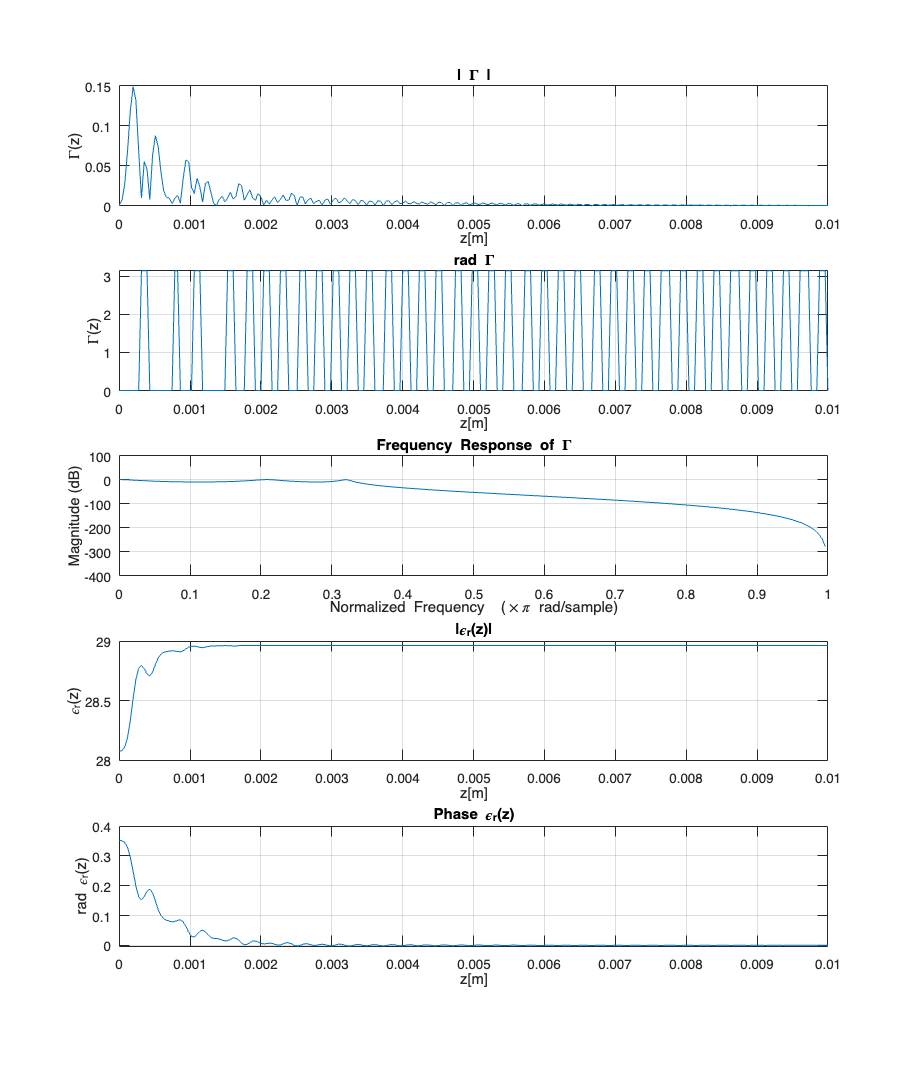

% Spacial variations

L = 1e-2;
N_L = 256;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 0.7*1e2;
vp = 0.15e8;
z = linspace(0, L, N_L);

k = omega/vp;

% we use a chebyshev's Low Pass Filter

kc = k*1e2; % cutoff
ks = k*3e2; % sampling freq
rp = 10; % ripple

% Calculate analog cutoff frequency and convert to digital
% wc = 2*pi*kc; % analog cutoff frequency
% wd = 2*pi*kc/ks; % digital cutoff frequency
kd = kc/ks;

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(kd, 0.5*kd, rp, 60);
[bc, ac] = cheby1(n, rp, Wn);

% take delta function as input
x = [1, zeros(1, N_L-1)];

Gamma = filter(bc, ac, x); % Gamma(z)
[Hz, w] = freqz(bc, ac, N_L); % freq resp

dGamma = gradient(Gamma); % Gamma'(z)

% find a and b
a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

% find eps(z)
epsz = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2);

% ode

figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(z, abs(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("| \Gamma |")

subplot(5,1,2)
plot(z, angle(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("rad \Gamma")

subplot(5,1,3)
plot(w/(pi), 20*log10(abs(Hz)));
xlabel('Normalized Frequency  (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
ylim([-400, 100]);
grid("on")
title('Frequency Response of \Gamma');

subplot(5,1,4)
plot(z, abs(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("|\epsilon_r(z)|")

subplot(5,1,5)
plot(z, angle(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("rad \epsilon_r(z)")
title("Phase \epsilon_r(z)")

### Determining switch positions

% geroemtric parameters

% DOES NOT MAKE SENSE

%{
W = 20e-6; S = 20e-6;
b = 1e-6;
d = 20e-6;

C11 = (2.*W./(b-S)).*epsz;
C12 = (W./S).*epsz;
Cson = (W./d).*epsz;

% Assuming odd mode - theoretical solution
Co_theo = C11+2.*C12;
pz = (epsz - Co_theo)/Cson;


figure
plot(z, real(pz))
grid("on")
xlabel("z[m]")
ylabel("p(z)")
title("Re p(z)") 
%}

Temporal change

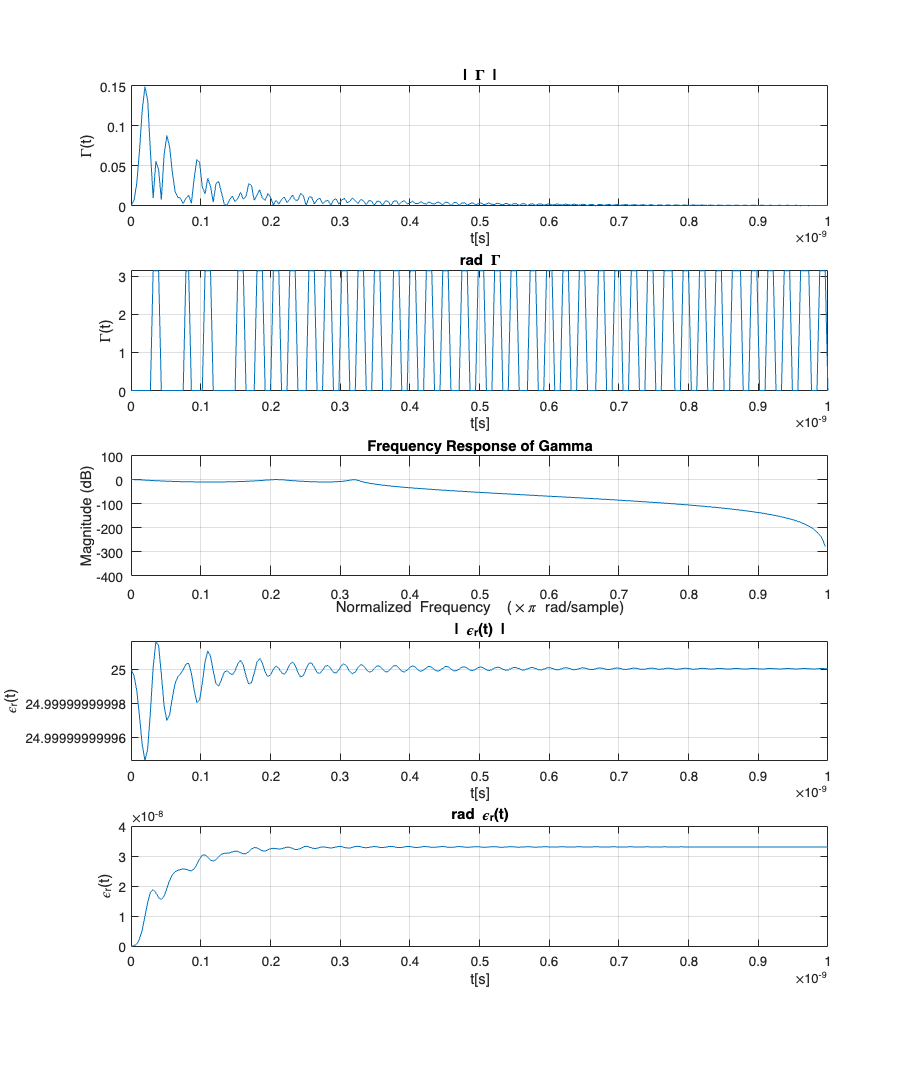

clear Gamma dGamma
T = 1e-9;
N_T = 256;
t = linspace(0, T, N_T);

% we use a chebyshev's Low Pass Filter

fc = omega; % cutoff frequency
fs = omega*6*pi; % sampling freq
rp = 10; % ripple

% Calculate analog cutoff frequency and convert to digital
wc = 2*pi*fc; % analog cutoff frequency
wd = 2*pi*fc/fs; % digital cutoff frequency

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(wd, 0.5*wd, rp, 60);
[bc, ac] = cheby1(n, rp, Wn);

% take delta function as input so that output will give Gamma(t)
x = [1, zeros(1, N_L-1)];

Gamma = filter(bc, ac, x); % Gamma(z)
[Ht, w] = freqz(bc, ac, N_T); % freq resp

dGamma = gradient(Gamma); % Gamma'(z)


a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);

D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
epst = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) - I.^(-1).*D ).^(-2);

figure2=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(t, abs(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("| \Gamma |")

subplot(5,1,2)
plot(t, angle(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("rad \Gamma")

subplot(5,1,3)
plot(w/(pi), 20*log10(abs(Ht)));
xlabel('Normalized Frequency  (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
ylim([-400, 100]);
grid("on")
title('Frequency Response of Gamma');

subplot(5,1,4)
plot(t, abs(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("| \epsilon_r(t) |")

subplot(5,1,5)
plot(t, angle(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("rad \epsilon_r(t)")